% Horizon study data
data_2_high = importdata("MPC_Np_2_N_sim_40_brysons_rule_high_disturbance_volatility.mat");
data_2_low = importdata("MPC_Np_2_N_sim_40_brysons_rule_low_disturbance_volatility.mat");
data_5_high = importdata("MPC_Np_5_N_sim_40_brysons_rule_high_disturbance_volatility.mat");
data_5_low = importdata("MPC_Np_5_N_sim_40_brysons_rule_low_disturbance_volatility.mat");
data_15 = importdata("MPC_Np_15_N_sim_40_brysons_rule_low_disturbance_volatility.mat");

x_2_high = data_2_high.x;
x_2_low = data_2_low.x;
x_5_high = data_5_high.x;
x_5_low = data_5_low.x;
x_15 = data_15.x;

u_2_high = data_2_high.u;
u_2_low = data_2_low.u;
u_5_high = data_5_high.u;
u_5_low = data_5_low.u;
u_15 = data_15.u;

% Weight study data
data_q_up = importdata("MPC_Np_5_Q_0.1_R_as_before.mat");
data_r_up = importdata("MPC_Np_5_R_0.3333_Q_as_before.mat");

x_q_up = data_q_up.x;
u_q_up = data_q_up.u;
x_r_up = data_r_up.x;
u_r_up = data_r_up.u;

% Baseline controller
data_PID = importdata("PID.mat");
x_PID = data_PID.x;
u_PID = data_PID.u;

t = data_2_high.t;


## True vs estimated + ctrl input

% x = x_5_low;
% x_hat = data_5_low.x_hat;
% u = u_5_low;
% % State estimation
% figure; hold on; grid on;
% 
% colours = lines(4); % consistent, visually distinct colours
% 
% for i = 1:4
%     % True (solid)
%     plot(t, x(i,2:end), ...
%         'Color', colours(i,:), ...
%         'LineWidth', 1.8);
% 
%     % Estimated (dashed)
%     plot(t, x_hat(i,2:end), ...
%         '--', ...
%         'Color', colours(i,:), ...
%         'LineWidth', 1.8);
% end
% 
% % Minimal legend: style explains meaning
% legend({'True', 'Estimated'}, 'Location', 'best');
% 
% xlabel('Time');
% ylabel('Temperature');
% title('True vs Estimated Temperatures');
% 
% % % Disturbance estimation
% % figure; hold on; grid on;
% % 
% % colour = [0.8500 0.3250 0.0980]; % pick a distinct colour (MATLAB default orange)
% % 
% % % True disturbance (solid)
% % plot(t, d(2:end), ...
% %     'Color', colour, ...
% %     'LineWidth', 1.8);
% % 
% % % Estimated disturbance (dashed)
% % plot(t, x_hat(5,2:end), ...
% %     '--', ...
% %     'Color', colour, ...
% %     'LineWidth', 1.8);
% % 
% % legend({'True disturbance', 'Estimated disturbance'}, 'Location', 'best');
% % 
% % xlabel('Time');
% % ylabel('Disturbance');
% % title('True vs Estimated Disturbance');
% 
% % Total Cost
% figure; hold on; grid on;
% 
% colour_1 = [0.20 0.55 0.65];
% colour_2 = [0.75 0.35 0.30];
% colour_3 = [0.50 0.60 0.30];
% colour_4 = [0.55 0.45 0.70];
% 
% % Input 1
% plot(t, cumsum(u(1,:))/100, ...
%     'Color', colour_1, ...
%     'LineWidth', 1.8);
% 
% % Input 2
% plot(t, cumsum(u(2,:))/100, ...
%     'Color', colour_2, ...
%     'LineWidth', 1.8);
% 
% % Input 3
% plot(t, cumsum(u(3,:))/100, ...
%     'Color', colour_3, ...
%     'LineWidth', 1.8);
% 
% % Input 4
% plot(t,cumsum(u(1,:) + u(2,:) + u(3,:))/100, ...
%     'Color',colour_4, ...
%     'Linewidth', 1.8);
% 
% legend({'Input 1', 'Input 2', 'Input 3', 'Total'}, 'Location', 'best');
% 
% xlabel('Time (hrs)');
% ylabel('Cost incurred (€)');
% title('Cost incurred over time');

## Comparison of low

% % State estimation
% figure; hold on; grid on;
% 
% colour_1 = [0.20 0.55 0.65];
% colour_2 = [0.75 0.35 0.30];
% colour_3 = [0.50 0.60 0.30];
% colour_4 = [0.55 0.45 0.70];
% 
% % Np = 2
% plot(t, mean(x_2_low(:,2:end)), ...
%     'Color', colour_1, ...
%     'LineWidth', 1.8);
% 
% % Np = 5
% plot(t, mean(x_5_low(:,2:end)), ...
%     'Color', colour_2, ...
%     'LineWidth', 1.8);
% 
% % Np = 15
% plot(t,mean(x_15(:,2:end)), ...
%     'Color', colour_3, ...
%     'LineWidth',1.8);
% yline(20, '--', 'LineWidth',1.2)
% 
% % Minimal legend: style explains meaning
% legend({'N_p=2', 'N_p=5', 'N_p=15', 'x_{ref}'}, Location="best");
% 
% xlabel('Time (hrs)');
% ylabel('Temperature (°C)');
% title('Temperature Evolution by N_p');
% 
% 
% 
% % Total Cost
% figure; hold on; grid on;
% 
% % 2
% plot(t, cumsum(sum(u_2_low(:,:)))/100, ...
%     'Color', colour_1, ...
%     'LineWidth', 1.8);
% 
% % 5
% plot(t, cumsum(sum(u_5_low(:,:)))/100, ...
%     'Color', colour_2, ...
%     'LineWidth', 1.8);
% 
% % 15
% plot(t, cumsum(sum(u_15(:,:)))/100, ...
%     'Color', colour_3, ...
%     'LineWidth', 1.8);
% 
% legend({'Np = 2', 'Np = 5', 'Np = 15'}, 'Location', 'best');
% 
% xlabel('Time (hrs)');
% ylabel('Total cost incurred (€)');
% title('Cost incurred over time');
% 


## Higher volatility disturbance comparison

% % Total Cost
% figure; hold on; grid on;
% 
% % 2
% plot(t, cumsum(sum(u_2_low(:,:)))/100, ...
%     'Color', colour_1, ...
%     'LineWidth', 1.8);
% 
% % 5
% plot(t, cumsum(sum(u_5_low(:,:)))/100, ...
%     'Color', colour_2, ...
%     'LineWidth', 1.8);
% 
% % % 2 (omitted since doesn't detectably change)
% % plot(t, cumsum(sum(u_2_high(:,:)))/100, ...
% %     'Color', colour_1, ...
% %     'LineWidth', 1.8);
% 
% % 5
% plot(t, cumsum(sum(u_5_high(:,:)))/100, ...
%     'Color', colour_4, ...
%     'LineWidth', 1.8);
% 
% 
% legend({'Np = 2','Np = 5 (steady)', 'Np = 5 (volatile)'}, 'Location', 'best');
% 
% xlabel('Time (hrs)');
% ylabel('Total cost incurred (€)');
% title('Cost incurred over time');


## Finding values

% % Average difference to x_ref
% avg_diff_2  = mean(abs(mean(x_2_low(:,2:end),  1) - 20));
% avg_diff_5  = mean(abs(mean(x_5_low(:,2:end),  1) - 20));
% avg_diff_15 = mean(abs(mean(x_15(:,2:end),     1) - 20));
% 
% fprintf('Np=2:  %.4f°C\n', avg_diff_2);
% fprintf('Np=5:  %.4f°C\n', avg_diff_5);
% fprintf('Np=15: %.4f°C\n', avg_diff_15);
% 
% % Average variance across time
% avg_var_2  = mean(var(x_2_low(:,2:end),  0, 1));
% avg_var_5  = mean(var(x_5_low(:,2:end),  0, 1));
% avg_var_15 = mean(var(x_15(:,2:end),     0, 1));
% 
% fprintf('Variance:\n');
% fprintf('Np=2:  %.4f\n', avg_var_2);
% fprintf('Np=5:  %.4f\n', avg_var_5);
% fprintf('Np=15: %.4f\n', avg_var_15);
% 
% % Total cost
% total_cost_2  = sum(sum(u_2_low(:,:))) / 100;
% total_cost_5  = sum(sum(u_5_low(:,:))) / 100;
% total_cost_15 = sum(sum(u_15(:,:)))    / 100;
% 
% fprintf('\nTotal cost:\n');
% fprintf('Np=2:  %.4f€\n', total_cost_2);
% fprintf('Np=5:  %.4f€\n', total_cost_5);
% fprintf('Np=15: %.4f€\n', total_cost_15);


## Weight stuff

% % State estimation
% figure; hold on; grid on;
% 
% colour_1 = [0.20 0.55 0.65];
% colour_2 = [0.75 0.35 0.30];
% 
% % Np = 2
% plot(t, mean(x_q_up(:,2:end)), ...
%     'Color', colour_1, ...
%     'LineWidth', 1.8);
% 
% % Np = 5
% plot(t, mean(x_r_up(:,2:end)), ...
%     'Color', colour_2, ...
%     'LineWidth', 1.8);
% 
% 
% % Minimal legend: style explains meaning
% legend({'Q high, R low', 'Q low, R high'}, Location="best");
% 
% xlabel('Time (hrs)');
% ylabel('Temperature (°C)');
% title('Temperature Evolution for different weights');
% 
% % Total Cost
% figure; hold on; grid on;
% 
% % 2
% plot(t, cumsum(sum(u_q_up(:,:)))/100, ...
%     'Color', colour_1, ...
%     'LineWidth', 1.8);
% 
% % 5
% plot(t, cumsum(sum(u_r_up(:,:)))/100, ...
%     'Color', colour_2, ...
%     'LineWidth', 1.8);
% 
% 
% legend({'Q high, R low', 'Q low, R high'}, 'Location', 'best');
% 
% xlabel('Time (hrs)');
% ylabel('Total cost incurred (€)');
% title('Cost incurred over time for different weights');


## Baseline controller comparison

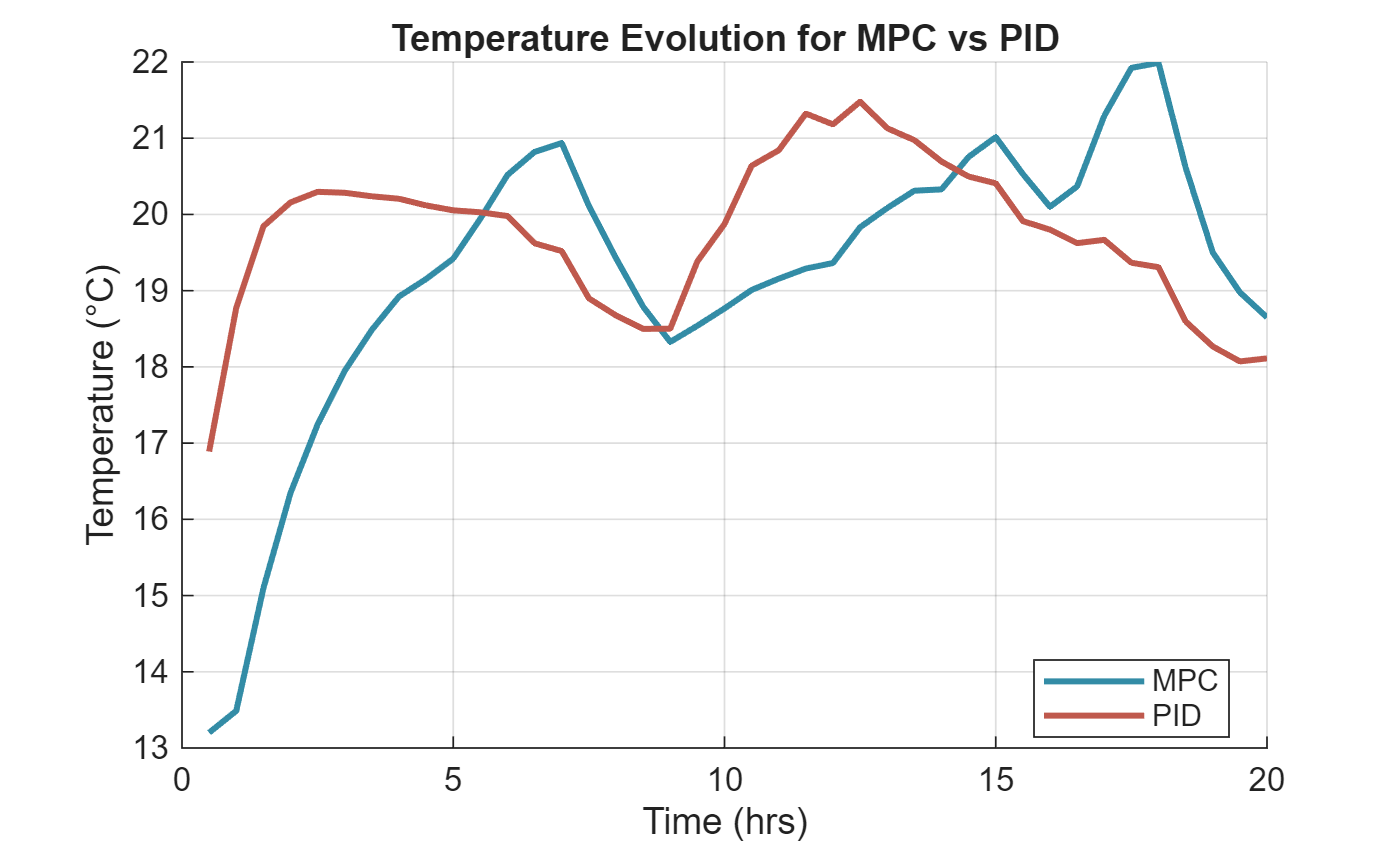

% State estimation
figure; hold on; grid on;

colour_1 = [0.20 0.55 0.65];
colour_2 = [0.75 0.35 0.30];

% Np = 2
plot(t, mean(x_5_low(:,2:end)), ...
    'Color', colour_1, ...
    'LineWidth', 1.8);

% Np = 5
plot(t, mean(x_PID(:,2:end)), ...
    'Color', colour_2, ...
    'LineWidth', 1.8);


% Minimal legend: style explains meaning
legend({'MPC', 'PID'}, Location="best");

xlabel('Time (hrs)');
ylabel('Temperature (°C)');
title('Temperature Evolution for MPC vs PID');

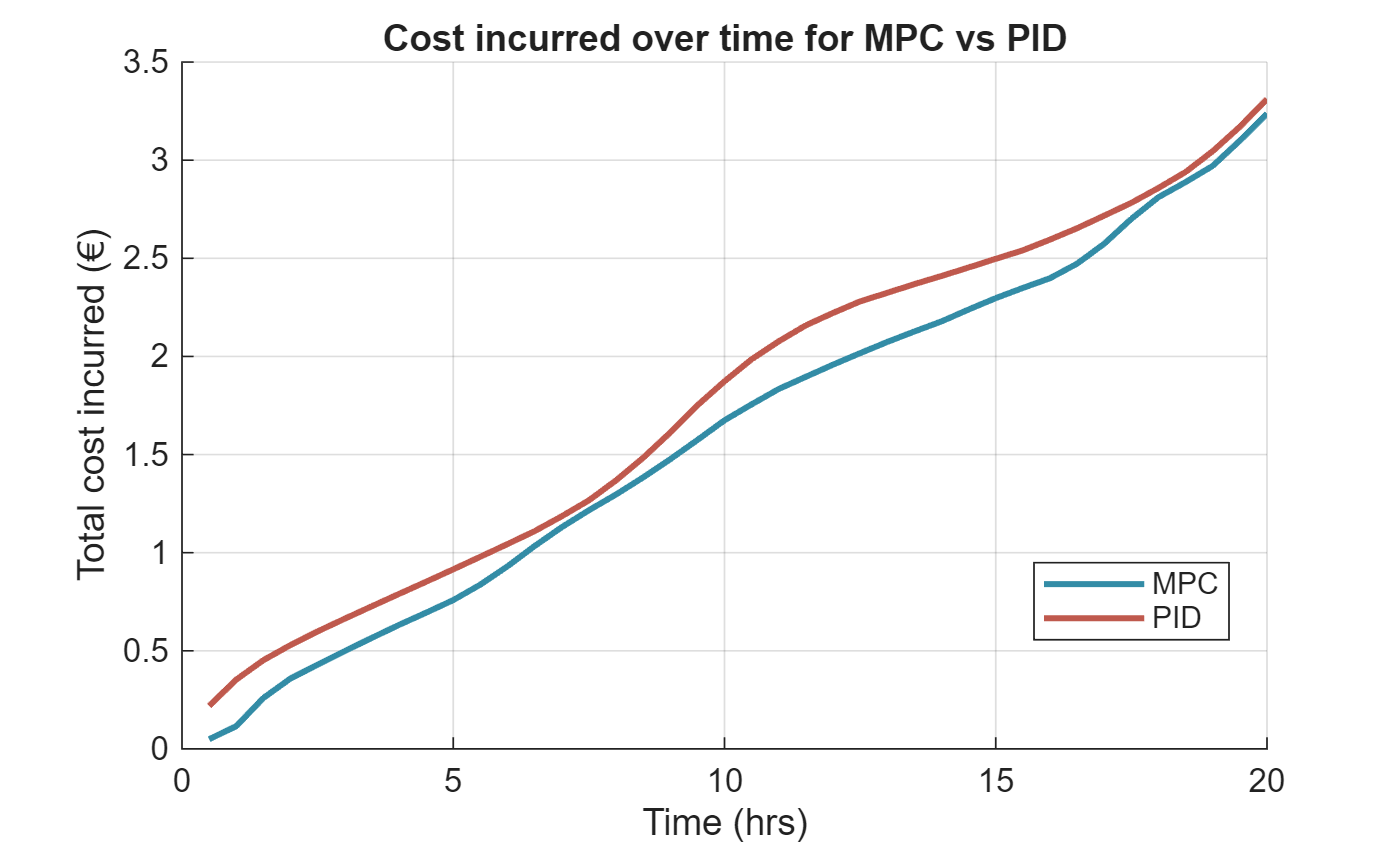


% Total Cost
figure; hold on; grid on;

% 2
plot(t, cumsum(sum(u_2_low(:,:)))/100, ...
    'Color', colour_1, ...
    'LineWidth', 1.8);

% 5
plot(t, cumsum(sum(u_PID(:,:)))/100, ...
    'Color', colour_2, ...
    'LineWidth', 1.8);


legend({'MPC', 'PID'}, 'Location', 'best');

xlabel('Time (hrs)');
ylabel('Total cost incurred (€)');
title('Cost incurred over time for MPC vs PID');